file locations

hcp: cd("/data1/datasets/hcp/125525/MNINonLinear/Results/rfMRI_REST1_7T_PA")

clear
storeFiles = '/home/liaoe2/ece8395_files' %directory to non-script proj files (sync with google drive)

storeFiles = '/home/liaoe2/ece8395_files'

storeScripts = '/fs1/rubinov_lab/emily/fall2023/fmri_class/project_scripts' %directory to latest scripts (sync with github)

storeScripts = '/fs1/rubinov_lab/emily/fall2023/fmri_class/project_scripts'

addpath(fullfile(storeScripts,"sigstarPackage"));

Run identification process using available scan combos

combos = combvec(1:4,1:4)';
combos = combos(combos(:,1)~=combos(:,2),:);
hcp_id_shen_whole={}; hcp_id_yan200_whole={}; hcp_id_yan400_whole={};
hcp_id_shen_nw={}; hcp_id_yan200_nw={}; hcp_id_yan400_nw={};
for ii=1:size(combos,1)
interestRows = combos(ii,:);
%WHOLE BRAIN 100 SUBJ
label_names="whole brain";
temp = runId("load",storeFiles, storeScripts,"100_hcp_fc_shen_whole.mat","shen_2mm_268_parcellation.nii",label_names,interestRows);
hcp_id_shen_whole = [hcp_id_shen_whole; cellfun(@sum, temp,'UniformOutput',false)];
temp=runId("load",storeFiles, storeScripts,"100_hcp_fc_yan200_whole.mat","200Parcels_Kong2022_17Networks_FSLMNI152_2mm.nii.gz",label_names,interestRows);
hcp_id_yan200_whole = [hcp_id_yan200_whole; cellfun(@sum, temp,'UniformOutput',false)];
temp=runId("load",storeFiles, storeScripts,"100_hcp_fc_yan400_whole.mat","400Parcels_Kong2022_17Networks_FSLMNI152_2mm.nii.gz",label_names,interestRows);
hcp_id_yan400_whole = [hcp_id_yan400_whole; cellfun(@sum, temp,'UniformOutput',false)];

% %7 NETWORKS 100 SUBJ
cd(storeFiles);
label_names=struct2cell(load("nw7_names"));
label_names = label_names{1};
temp=runId("load",storeFiles, storeScripts,"100_hcp_fc_shen_nw7.mat","shen_2mm_268_parcellation.nii",label_names,interestRows);
hcp_id_shen_nw = [hcp_id_shen_nw; cellfun(@sum, temp,'UniformOutput',false)];
temp=runId("load",storeFiles, storeScripts,"100_hcp_fc_yan200_nw7.mat","200Parcels_Kong2022_17Networks_FSLMNI152_2mm.nii.gz",label_names,interestRows);
hcp_id_yan200_nw = [hcp_id_yan200_nw; cellfun(@sum, temp,'UniformOutput',false)];
temp=runId("load",storeFiles, storeScripts,"100_hcp_fc_yan400_nw7.mat","400Parcels_Kong2022_17Networks_FSLMNI152_2mm.nii.gz",label_names,interestRows);
hcp_id_yan400_nw = [hcp_id_yan400_nw; cellfun(@sum, temp,'UniformOutput',false)];
load("100_hcp_tSNR_yan400_nw7.mat"); hcp_tSNR_yan400_nw = [hcp_tSNR_yan400_nw; cellfun(@sum, hcp_tSNR_yan400_nw,'UniformOutput',false)];
end
hcp_id_shen_whole=collapseNwTables(combos,hcp_id_shen_whole,1); %format the outputs
hcp_id_yan200_whole=collapseNwTables(combos,hcp_id_yan200_whole,1);
hcp_id_yan400_whole=collapseNwTables(combos,hcp_id_yan400_whole,1);
hcp_id_shen_nw=collapseNwTables(combos,hcp_id_shen_nw,7);
hcp_id_yan200_nw=collapseNwTables(combos,hcp_id_yan200_nw,7);
hcp_id_yan400_nw=collapseNwTables(combos,hcp_id_yan400_nw,7);
%hcp_tSNR_yan400_nw=collapseNwTables(combos,hcp_tSNR_yan400_nw,7);

%run whole brain report
%cd(fullfile(storeFiles,"outputs"));
[~,wholeBrain]=idReportNw([hcp_id_shen_whole hcp_id_yan200_whole hcp_id_yan400_whole] ,["Shen","Yan200","Yan400"]);

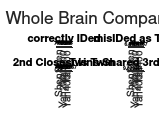

sgtitle("Whole Brain Comparison");
exportgraphics(gcf,'wholeBrain.png');

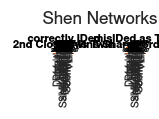


%run nw report
%cd(fullfile(storeFiles,"outputs"));
[~,shenNw]=idReportNw(hcp_id_shen_nw,label_names);
sgtitle("Shen Networks");
exportgraphics(gcf,'shenNw.png');

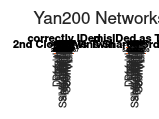

[~,yan200Nw]=idReportNw(hcp_id_yan200_nw,label_names);
sgtitle("Yan200 Networks");
exportgraphics(gcf,'yan200Nw.png');

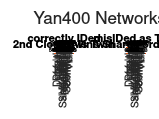

[~,yan400Nw] = idReportNw(hcp_id_yan400_nw,label_names);
sgtitle("Yan400 Networks");
exportgraphics(gcf,'yan400Nw.png');

%yan400Nw = idReportNw(hcp_tSNR_yan400_nw,label_names);

**FUNCTIONS**

function idTable = runId(toggle,storeFiles, storeScripts, outputFileName, parcFileName,label_names,interestRows)
%takes a scans by subj cell array containing FC matrix in each cell
if contains(toggle, "load")
%LOAD SAVED VERSION:
cd(fullfile(storeFiles,'outputs'));
subj_fc = struct2cell(load(outputFileName));
subj_fc=subj_fc{1};
else %apply whole brain analysis (nw analyses use separate code file)
%100 subj:
subjIds=[125525 192439 169343 627549 159239 249947 200614 861456 111312 144226 102816 680957 176542 246133 135124 463040 547046 901139 412528 951457 137128 859671 156334 833249 148133 771354 132118 436845 181232 191841 102311 145834 233326 352738 146432 818859 128935 200311 199655 251833 397760 467351 115017 782561 195041 204521 131217 365343 169444 901442 177645 212419 385046 878877 191033 872764 165436 971160 134627 943862 757764 905147 178647 182436 395756 644246 146937 401422 130518 562345 185442 601127 104416 187345 126426 146735 263436 320826 169747 751550 209228 765864 318637 926862 116726 257845 552241 973770 186949 995174 146129 783462 164636 214524 115825 178243 198653 581450 180533 654552];
%50 subj
%subjIds=[125525 192439 169343 627549 159239 249947 200614 861456 111312 144226 102816 680957 176542 246133 135124 463040 547046 901139 412528 951457 137128 859671 156334 833249 148133 771354 132118 436845 181232 191841 102311 145834 233326 352738 146432 818859 128935 200311 199655 251833 397760 467351 115017 782561 195041 204521 131217 365343 169444 901442];
cd(storeFiles)
parcInfo = niftiinfo(parcFileName);
parcImage = niftiread(parcFileName);
%apply parc & fc
subj_fc = hcp7tFC(subjIds,parcImage);
cd(fullfile(storeFiles,"outputs"));
save(outputFileName,'subj_fc');
cd(storeScripts)
end

numCorrectlyId=[]; numIdAsTwin=[]; numSecondIsTwin=[]; numSameThirdClosest=[]; numCorrIdAndSecondIsTwin=[];
for ii_page = 1:size(subj_fc,3) %for each page in the FC data (1 per network, only 1 if whole brain)
%CHECK ID RESULTS
idTable{ii_page} = makeIdTable(subj_fc(:,:,ii_page),interestRows); %note: uses scan1 as database, scan3 as test
numCorrectlyId=[numCorrectlyId sum(idTable{ii_page}.correctlyId)];
numIdAsTwin = [numIdAsTwin sum(idTable{ii_page}.idAsTwin)];
numSecondIsTwin = [numSecondIsTwin sum(idTable{ii_page}.secondIsTwin)];
numCorrIdAndSecondIsTwin = [numCorrIdAndSecondIsTwin sum((idTable{ii_page}.secondIsTwin)&(idTable{ii_page}.correctlyId))];
numSameThirdClosest = [numSameThirdClosest sum((idTable{ii_page}.sameThirdClosest)&(idTable{ii_page}.correctlyId)&(idTable{ii_page}.secondIsTwin))]; %among those correctly IDd, and re
numSubj = height(idTable{ii_page});
end
end

Applying parcellation and computing FC

function subj_fc = hcp7tFC(subjIds,parcImage)
%50 subj:
%subjIds=[125525 192439 169343 627549 159239 249947 200614 861456 111312 144226 102816 680957 176542 246133 135124 463040 547046 901139 412528 951457 137128 859671 156334 833249 148133 771354 132118 436845 181232 191841 102311 145834 233326 352738 146432 818859 128935 200311 199655 251833 397760 467351 115017 782561 195041 204521 131217 365343 169444 901442];
%100 subj:
%subjIds=[125525 192439 169343 627549 159239 249947 200614 861456 111312 144226 102816 680957 176542 246133 135124 463040 547046 901139 412528 951457 137128 859671 156334 833249 148133 771354 132118 436845 181232 191841 102311 145834 233326 352738 146432 818859 128935 200311 199655 251833 397760 467351 115017 782561 195041 204521 131217 365343 169444 901442 177645 212419 385046 878877 191033 872764 165436 971160 134627 943862 757764 905147 178647 182436 395756 644246 146937 401422 130518 562345 185442 601127 104416 187345 126426 146735 263436 320826 169747 751550 209228 765864 318637 926862 116726 257845 552241 973770 186949 995174 146129 783462 164636 214524 115825 178243 198653 581450 180533 654552];
subjFolders = [strcat("/data1/datasets/hcp/",string(subjIds),"/MNINonLinear/Results/rfMRI_REST1_7T_PA"); ...
    strcat("/data1/datasets/hcp/",string(subjIds),"/MNINonLinear/Results/rfMRI_REST2_7T_AP"); ...
    strcat("/data1/datasets/hcp/",string(subjIds),"/MNINonLinear/Results/rfMRI_REST3_7T_PA"); ...
    strcat("/data1/datasets/hcp/",string(subjIds),"/MNINonLinear/Results/rfMRI_REST4_7T_AP")];
subjFiles = ["rfMRI_REST1_7T_PA_hp2000_clean.nii.gz" "rfMRI_REST2_7T_AP_hp2000_clean.nii.gz" "rfMRI_REST3_7T_PA_hp2000_clean.nii.gz" "rfMRI_REST4_7T_AP_hp2000_clean.nii.gz"];
dne=[]; %collect names of folders not found
totalFiles=size(subjFolders,1);
totalSubjs=size(subjFolders,2);

parfor ii_subj=1:totalSubjs %PARFOR
for jj_scan=1:totalFiles
        if exist(subjFolders{jj_scan,ii_subj},'dir')
        cd(subjFolders{jj_scan,ii_subj})
        %hcpInfo = niftiinfo("rfMRI_REST1_7T_PA_hp2000_clean.nii.gz");
        subj_scan = niftiread(subjFiles(jj_scan));
        subj_scan_reg = applyParcImage(parcImage,subj_scan); %reg x t
        subj_fc{jj_scan,ii_subj} = calcFC(subj_scan_reg); %whole brain FC
        else 
            dne = [dne subjFolders{jj_scan,ii_subj}];
            subj_fc{jj_scan,ii_subj}=nan(max(parcImage,[],'all'),max(parcImage,[],'all'));
        end
    end
end
end

function region_timeseries = applyParcImage(parc,vol)
num_reg = max(parc(:));
%parc is 3D parcellation reference
%vol is 4D data of interest
parc = imresize3(parc,size(vol,1:3),'nearest');
parc_flatten = reshape(parc,numel(parc)/size(parc,4),[]); %flatten parc to col vector (length numvoxels)
vol_flatten = reshape(vol,numel(vol)/size(vol,4),[]); %flatten vol to voxels x time vector

%calculate region time series as avg over parcels in the region. Output: regionsxtime
vol_dim = size(vol);
region_timeseries = nan(num_reg, vol_dim(4));
parfor i = 1:num_reg %PARFOR, for each region
    region_timeseries(i, :) = mean(vol_flatten(parc_flatten==i,:), 1, 'omitnan'); 
end
end

function fc = calcFC(region_timeseries)
fc = corr(region_timeseries'); %correlations between all cols
% imagesc(fc)
% xlabel('brain regions')
% ylabel('brain regions')
% axis square
% colorbar
end

Making Identification Table

function idTable = makeIdTable(subj_fc,interestRows)
[identifiedAs secondClosest thirdClosest]  = findMatch(subj_fc,interestRows);
correctId=1:size(subj_fc,2);
twinId = 1:size(subj_fc,2); twinId(2:2:end)=twinId(2:2:end)-1; twinId(1:2:end)=twinId(1:2:end)+1;
thirdClosestOfTwin = thirdClosest(twinId);
idTable=table;
idTable.identifiedAs = identifiedAs(:);
idTable.secondClosest = secondClosest(:);
idTable.thirdClosest = thirdClosest(:);
idTable.correctlyId = (identifiedAs(:)==correctId(:));
idTable.idAsTwin = (identifiedAs(:)==twinId(:));
idTable.secondIsTwin = (secondClosest(:)==twinId(:));
idTable.sameThirdClosest = (thirdClosest(:)==thirdClosestOfTwin(:));
end

function [identifiedAs secondClosest thirdClosest vectorCorr] = findMatch(cellInput,interestRows)
%interestRows = [1,2]; %use scan1 as database, scan3 as test
cellInput = expandNans(cellInput);
makeVectors = cellfun(@(x) x(:), cellInput, 'UniformOutput',false); %false uniform output to return as cell
for ii=interestRows
horzVectors{ii} = horzcat(makeVectors{ii,:}); % for target and database scans, turn each subjs connectivity matrix into a vector. 2 cells contain (regxreg) x time
end
database = horzVectors{interestRows(1)};
target = horzVectors{interestRows(2)};
vectorCorr = corr(database,target); %correlations between each dataset and each target
[~,sortedIds]=sort(vectorCorr,'descend','MissingPlacement','last'); %sort corr for each target
identifiedAs = sortedIds(1,:);
secondClosest = sortedIds(2,:);
thirdClosest = sortedIds(3,:);
end

deal with missing scans

function cellArray = expandNans(cellArray)
%fill placeholder nans when missing scan
nanLocations = cellfun(@(x) any(isnan(x(:))), cellArray);
[row,col,page]=ind2sub(size(cellArray),find(nanLocations));
pageNums = unique(page);
for kk=1:length(pageNums)
%use first subj first scan as size reference
[makerows,makecols] = size(cellArray{1, 1, pageNums(kk)}); 
cellArray(row(page==pageNums(kk)),col(page==pageNums(kk)),pageNums(kk)) = {nan(makerows, makecols)};
end
end

format networks id result output

function id_nw=collapseNwTables(combos,id_nw,totalNetworks)
db_target=table();
db_target.database=combos(:,1); db_target.target=combos(:,2);
for ii=1:totalNetworks
    id_nw{1,ii} = vertcat(id_nw{:,ii});
    id_nw = cellfun(@(x) x(:, {'correctlyId', 'idAsTwin','secondIsTwin','sameThirdClosest'}), id_nw, 'UniformOutput', false);
end
id_nw=id_nw(1,:);
id_nw=cellfun(@(x) [db_target x], id_nw, 'UniformOutput', false);
end

make report graphics

function [getPlots getMeans]=idReportNw(hcp_id,label_names)
meanNumSubj=cellfun(@(x) mean(x), hcp_id, 'UniformOutput', false);
stdNumSubj=cellfun(@(x) std(x), hcp_id, 'UniformOutput', false);
getMeans = {}; getStds = {};

interestVar={'correctlyId','idAsTwin','secondIsTwin','sameThirdClosest'};
varTitle={'correctly IDed','misIDed as Twin','2nd Closest Is Twin','Twins Shared 3rd Closest'};
pvals=checkSig(hcp_id,label_names,interestVar);
figure; getPlots = tiledlayout(2,2);
for ii=1:length(interestVar)
getStds{ii} = cellfun(@(x) std(x{:, interestVar(ii)}), hcp_id);
getMeans{ii} =cellfun(@(x) mean(x{:, interestVar(ii)}),hcp_id);
% %BARPLOT RESULTS FOR NETWORKS
nexttile
tempMean=getMeans{ii};
b=bar(tempMean); ylim([0 100]); ylabel({"Mean Number of Subj","(out of 100 total)"});
set(gca,'XTick',1:numel(label_names), 'XTickLabel',label_names);
set(gca,'TickLength',[0 0]);
xtickangle(90);
xtips = b(1).XEndPoints;
ytips = b(1).YEndPoints+getStds{ii};
tiplabels = string(getMeans{ii});text(xtips,ytips,tiplabels,'HorizontalAlignment','center',...
     'VerticalAlignment','bottom','FontSize',4);
hold on
er = errorbar(1:numel(label_names),getMeans{ii},getStds{ii});   
er.LineStyle = 'none';  
title(varTitle(ii))
hold off
%H=sigstar(num2cell(pvals{2,ii}(1:2,:),1), cell2mat(pvals{2,ii}(3,:)));
end
end

function reportSig=checkSig(cellData,compareVar,interestVar)
%calculate the p values by paired t test
compareVar=cellstr(compareVar);
for jj=1:length(interestVar)
compareVar = compareVar(:)';
combos = nchoosek(1:length(compareVar),2); 
comboLabel = [compareVar(combos(:,1));compareVar(combos(:,2));];

for ii=1:size(combos,1)
    [~,pvals{ii}]=ttest(cellData{combos(ii,1)}{:,interestVar(jj)},cellData{combos(ii,2)}{:,interestVar(jj)});
    if pvals{ii}<0.001
       stars{ii}="***";
    elseif pvals{ii}<0.01
        stars{ii}="**";
    elseif pvals{ii}<0.05
        stars{ii}="*";      
    else
        stars{ii}=[];
    end
end
reportSig{jj}=[num2cell(combos');pvals;stars;comboLabel];
end
reportSig=[interestVar;reportSig];
end